# lab1 - Pietro Alovisi

## Setup

% add path containing lab files
addpath('../LabFiles/Functions/');
addpath('../LabFiles/Images/');
addpath('../LabFiles/Images-m/');

# Descrete Fourier transform

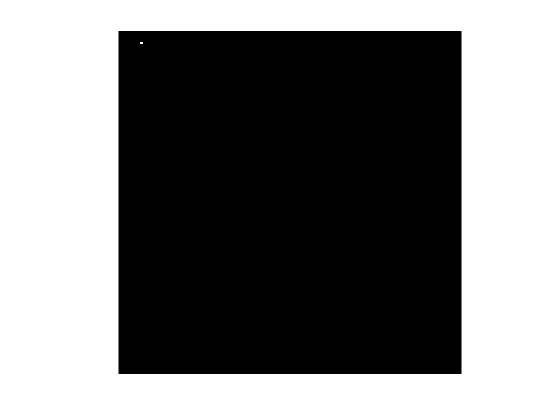

Fhat = zeros(128, 128);

p = 5; 
q = 9;
Fhat(p , q ) = 1;
figure(1);
showgrey(Fhat);

now let's compute the fourier transform

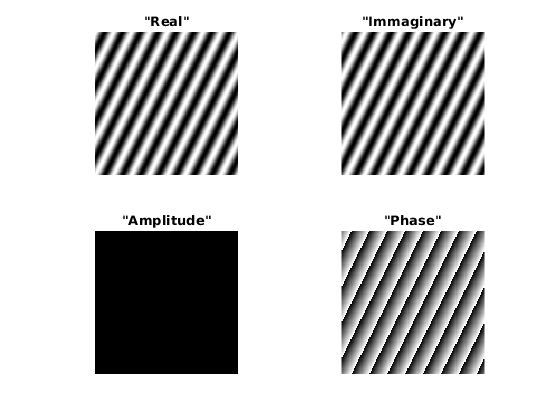


F = ifft2(Fhat);
Fabsmax = max(abs(F(:)));
figure(2);
subplot(2,2,1);
showgrey(real(F), 64, -Fabsmax, Fabsmax)
title "Real";

subplot(2,2,2);
showgrey(imag(F), 64, -Fabsmax, Fabsmax)
title "Immaginary";

subplot(2,2,3);
showgrey(log(abs(F)), 64, -Fabsmax, Fabsmax)
title "Amplitude";

subplot(2,2,4);
showgrey(angle(F), 64, -pi, pi)
title "Phase";

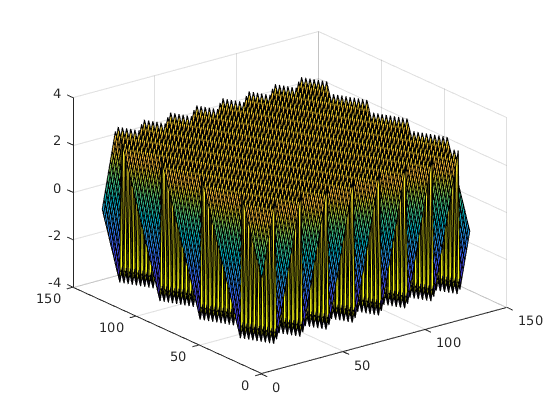

figure();
[X,Y]= meshgrid(1:128,1:128);
surf(X,Y,angle(F));

## Question 1

fftwave(5,9,128);

sadas

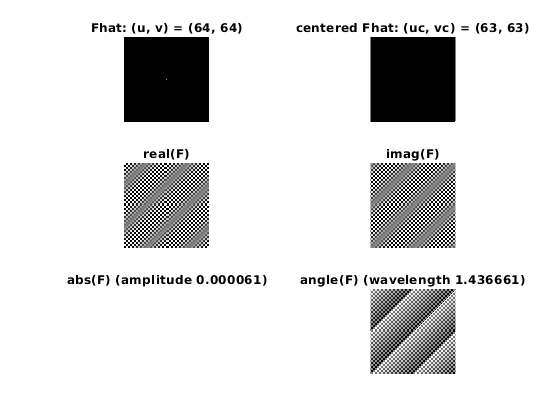

points = [5, 9; 9, 5; 17, 9; 17, 121;5, 1;125, 1];

for c =  1:size(points,1)
    %title(f.Children(end),sprintf("Point %d, %d",points(c,1),points(c,2)));
    fftwave(points(c,1),points(c,2));
end
p = 64;
q = 64;
fftwave(p,q,128);

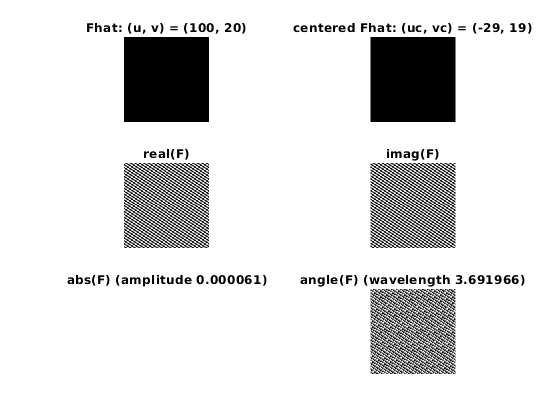

p = 100;
q = 20;
fftwave(p,q,128);

# Lienarity

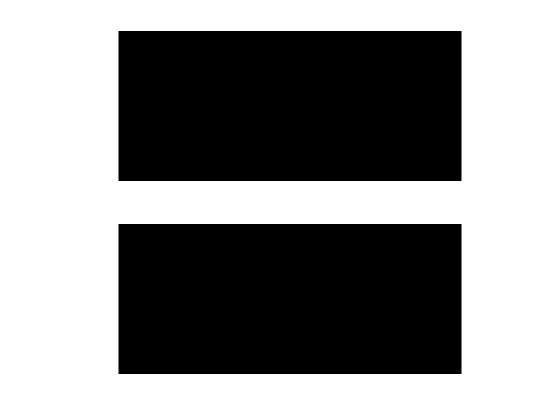

F = [ zeros(56, 128); ones(16, 128); zeros(56, 128)];
G = F';
H = F + 2 * G;

figure();
showgrey(F);

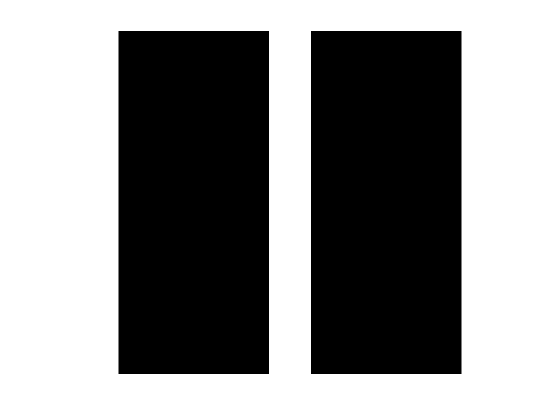

showgrey(G);

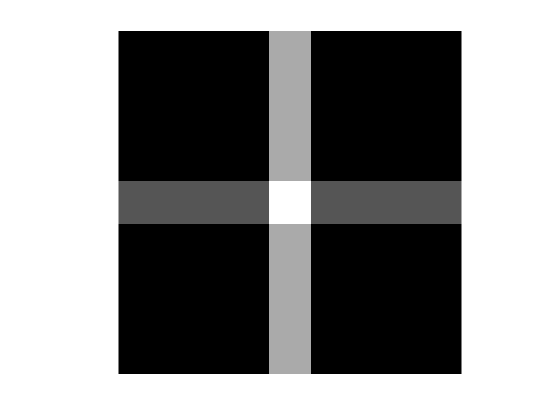

showgrey(H);

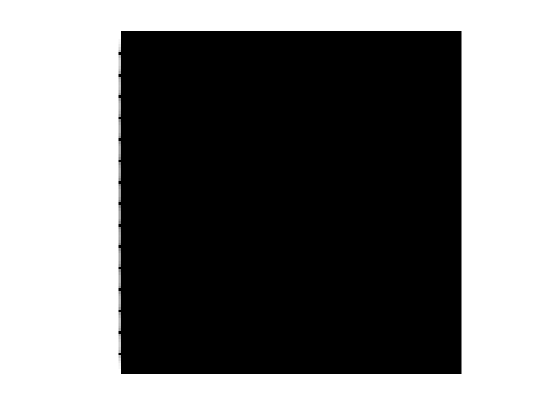

Fhat = fft2(F);
Ghat = fft2(G);
Hhat = fft2(H);

showgrey(log(1 + abs(Fhat)));

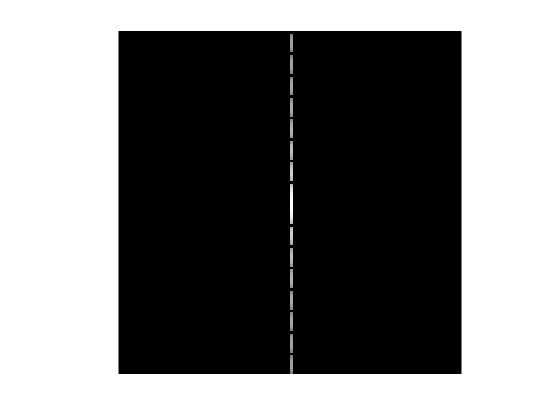

showgrey(log(1 + abs(fftshift(Fhat))));

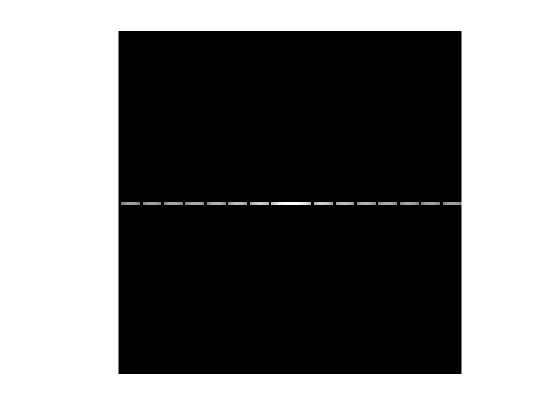

showgrey(log(1 + abs(fftshift(Ghat))));

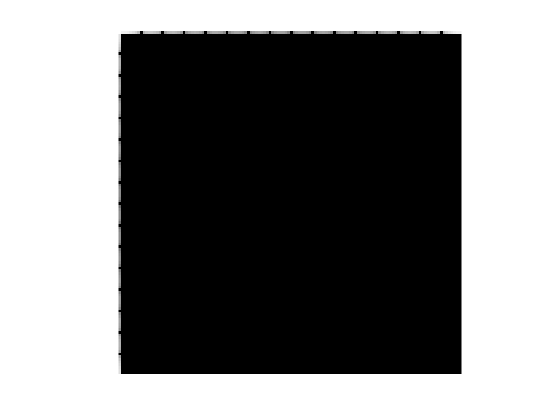

showgrey(log(1 + abs(Hhat)));

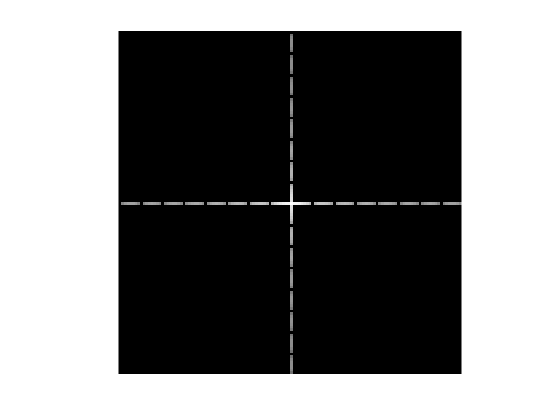

showgrey(log(1 + abs(fftshift(Hhat))));

# Multiplication

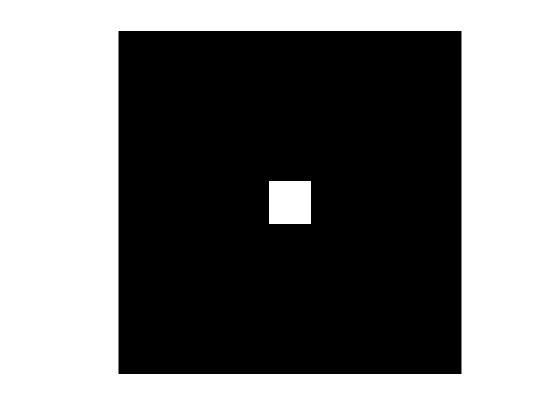

figure();
%With F and G as previously defined
F = [ zeros(56, 128); ones(16, 128); zeros(56, 128)];
G = F';
%Try the following commands
showgrey(F .* G);

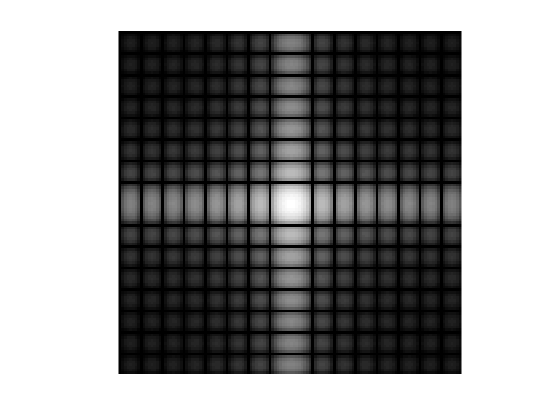

showfs(fft2(F .* G));

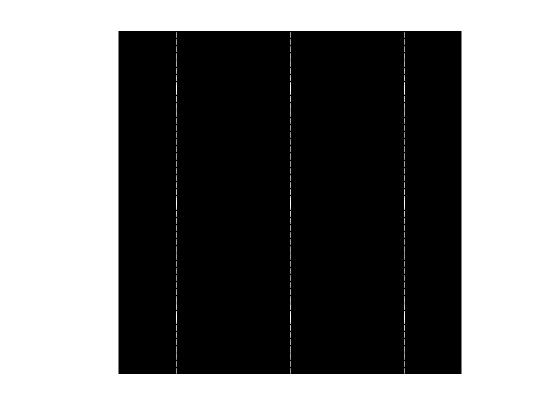

Fhat = fft2(F);
Ghat = fft2(G);

Fhat = [Fhat Fhat Fhat;
        Fhat Fhat Fhat;
        Fhat Fhat Fhat];

showfs(Fhat);

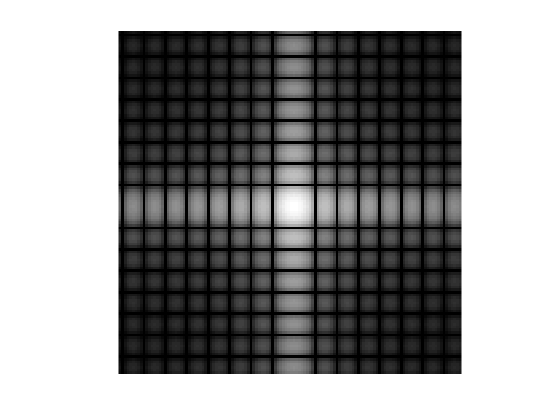

C = conv2(Fhat,Ghat,'valid');
C = C(129:256,129:256)/(10000);
%showgrey(log(1 + abs(fftshift(C))));
showfs(C);

showgrey(abs(ifft2(C)));

# Scaling

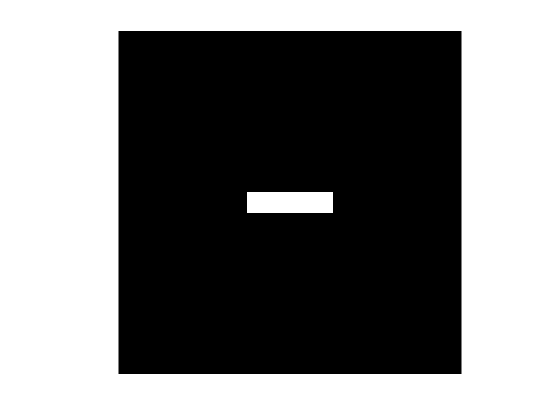


F = [zeros(60, 128); ones(8, 128); zeros(60, 128)] .* ...
[zeros(128, 48) ones(128, 32) zeros(128, 48)];

showgrey(F);

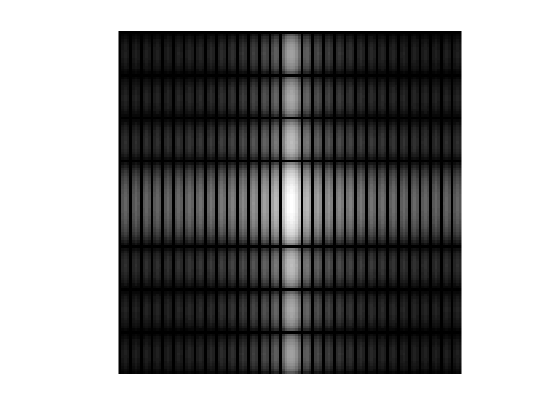

Fhat = fft2(F);
showfs(Fhat);

# Rotation

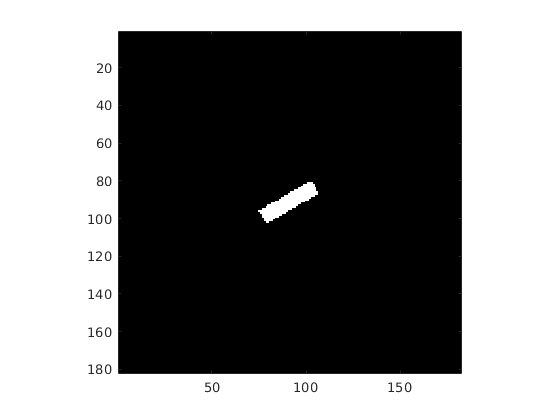

alpha = 30;

G = rot(F, alpha);
showgrey(G)
axis on

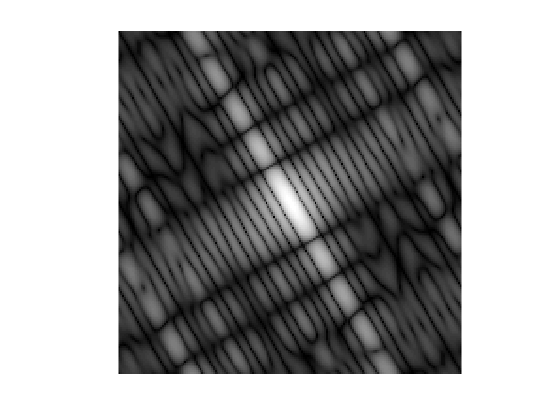


Ghat = fft2(G);
showfs(Ghat);

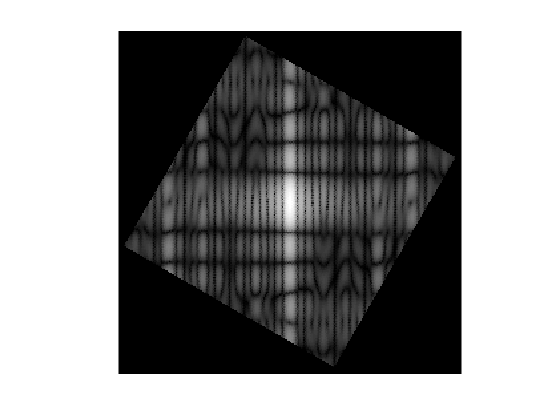

Hhat = rot(fftshift(Ghat), -alpha );
showgrey(log(1 + abs(Hhat)));

# Information in Fourier phase and magnitude

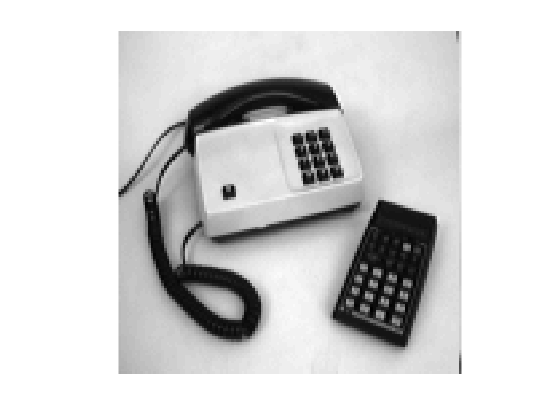

img = phonecalc128;
figure();
showgrey(img)

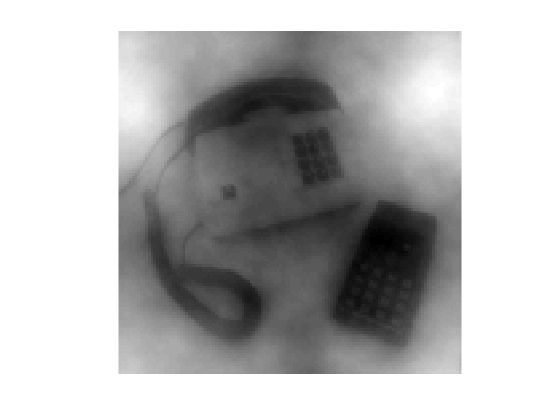

t_img = pow2image(img, 10e-10);
showgrey(t_img);

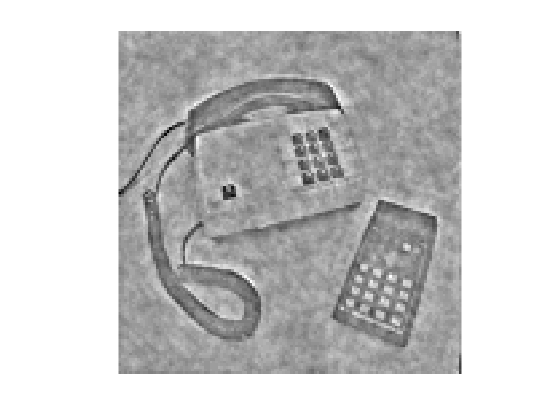

t_img = pow2image(img, 1);
showgrey(t_img);

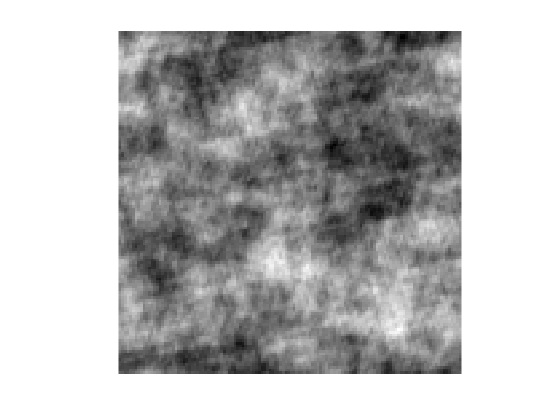

t_img = randphaseimage(img);
showgrey(t_img);

# Gaussian convolution implemented via FFT

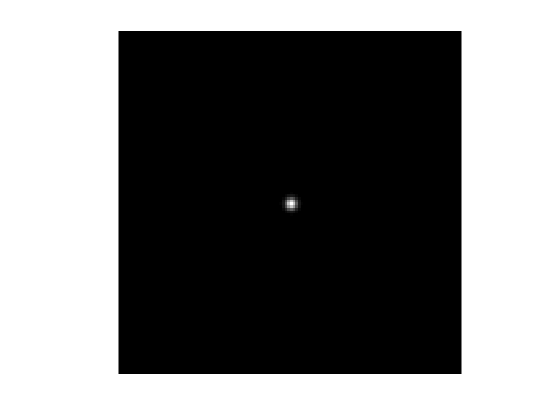

figure();
psf = gaussfft(deltafcn(128, 128), 2);
showgrey(psf);

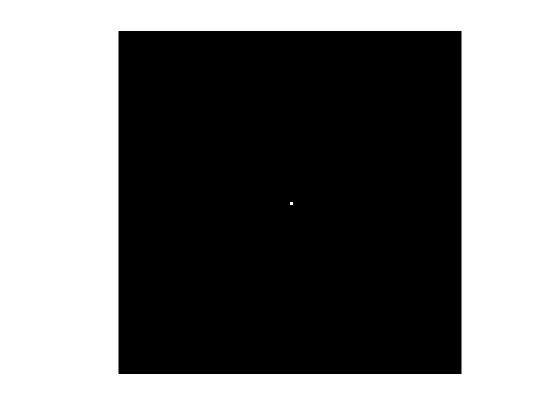

ans =     0.0133    0.0000
    0.0000    0.0133


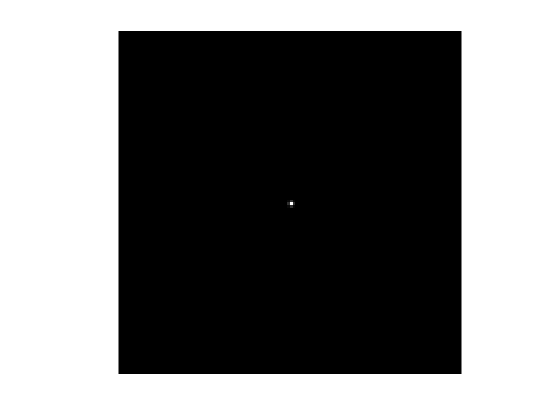

ans =     0.2811    0.0000
    0.0000    0.2811


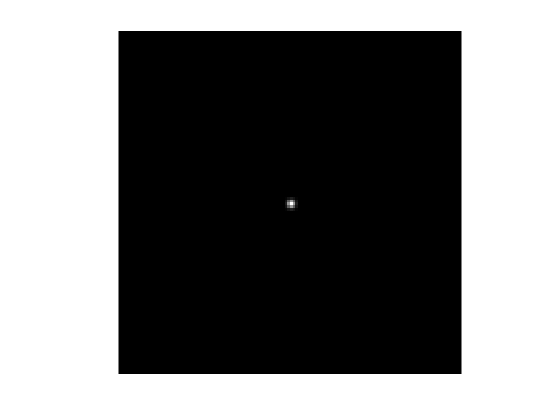

ans =     1.0000    0.0000
    0.0000    1.0000


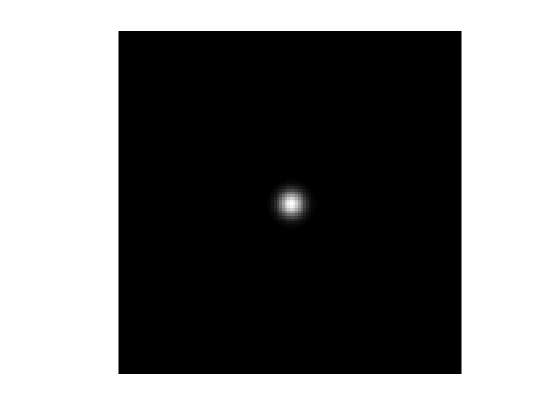

ans =    10.0000    0.0000
    0.0000   10.0000


figure();
for t = [0.1,0.3,1.0,10.0]
    psf = gaussfft(deltafcn(128, 128), t);
    figure();
    showgrey(psf);
    variance(psf)
end

# Smoothing

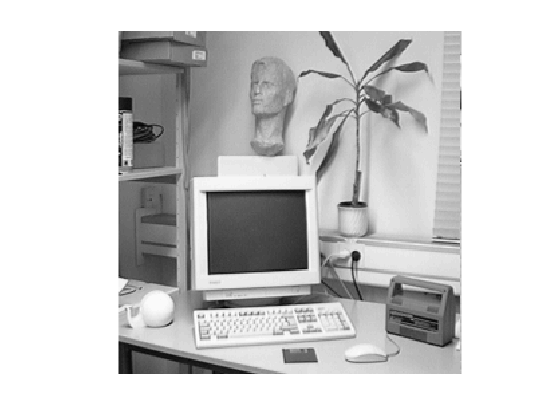

figure();

office = office256;
add = gaussnoise(office, 16);
sap = sapnoise(office, 0.1, 255);

showgrey(office);

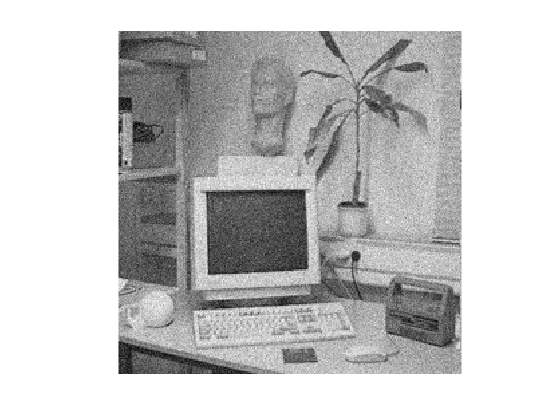

showgrey(add);

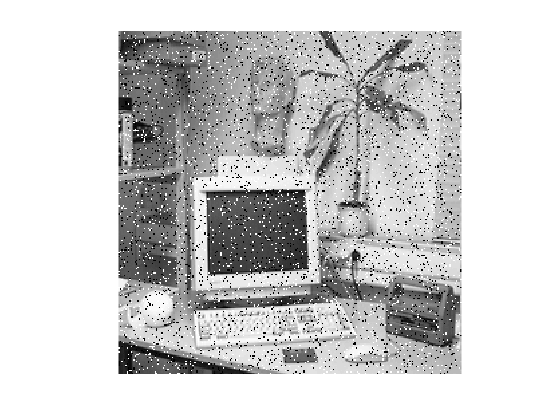

showgrey(sap);

## Gauss noise

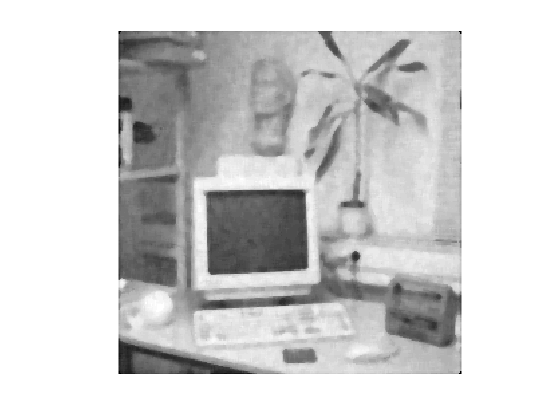


out = medfilt(add,5);
showgrey(out)

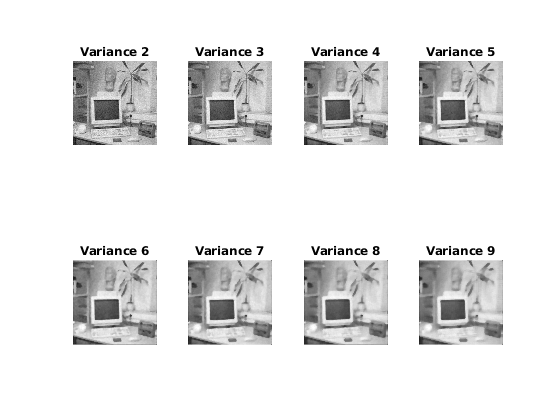


figure();

t = [2,3,4,5,6,7,8,9];

for j = 1:8
    subplot(2,4,j);
    out = medfilt(add,t(j));
    showgrey(out);
    title(sprintf("Variance %g",t(j)));
end

## Gaussian filter

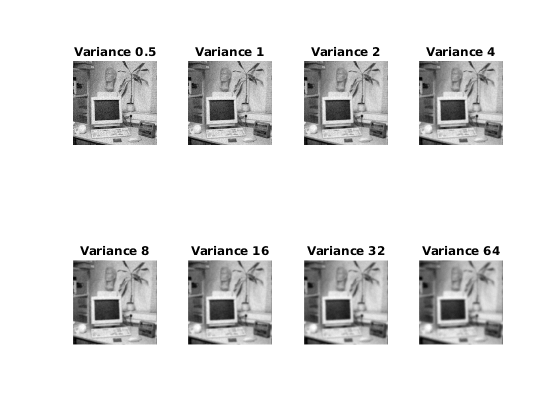

figure();

t = [0.5,1.0,2,4,8,16,32,64];

for j = 1:8
    subplot(2,4,j);
    out = gaussfft(add,t(j));
    showgrey(out);
    title(sprintf("Variance %g",t(j)));
end

## Ideal filter

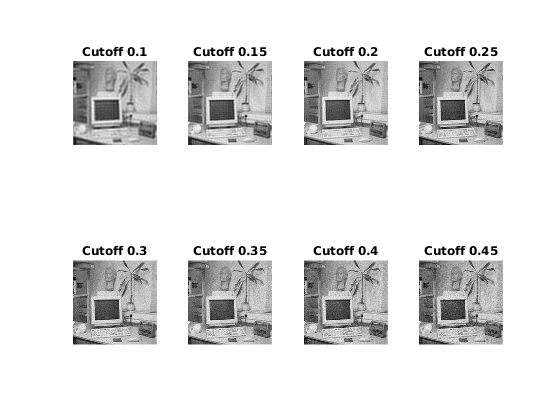

figure();

t = 0.1:0.05:0.5;

for j = 1:8
    subplot(2,4,j);
    out = ideal(add,t(j));
    showgrey(out);
    title(sprintf("Cutoff %g",t(j)));
end

## Salt and pepper

## Median filter

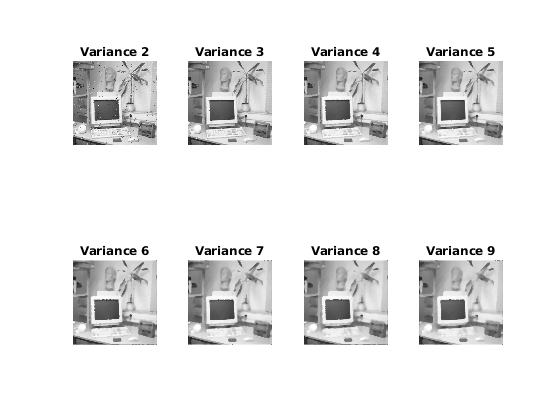

figure();

t = [2,3,4,5,6,7,8,9];

for j = 1:8
    subplot(2,4,j);
    out = medfilt(sap,t(j));
    showgrey(out);
    title(sprintf("Variance %g",t(j)));
end

## Gaussian filter

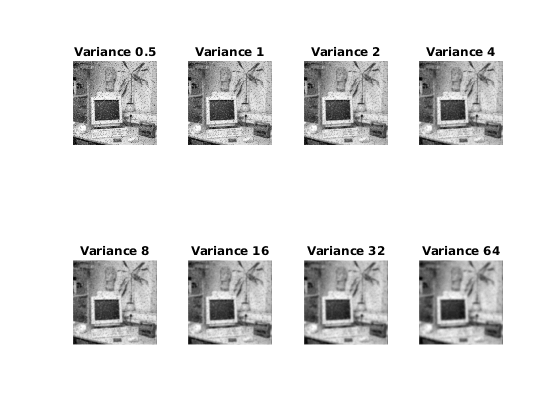

figure();

t = [0.5,1.0,2,4,8,16,32,64];

for j = 1:8
    subplot(2,4,j);
    out = gaussfft(sap,t(j));
    showgrey(out);
    title(sprintf("Variance %g",t(j)));
end

## Ideal filter

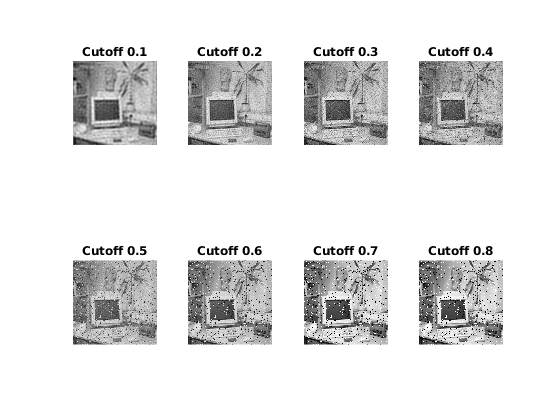

figure();

t = 0.1:0.1:0.8;

for j = 1:8
    subplot(2,4,j);
    out = ideal(sap,t(j));
    showgrey(out);
    title(sprintf("Cutoff %g",t(j)));
end

# Subsampling

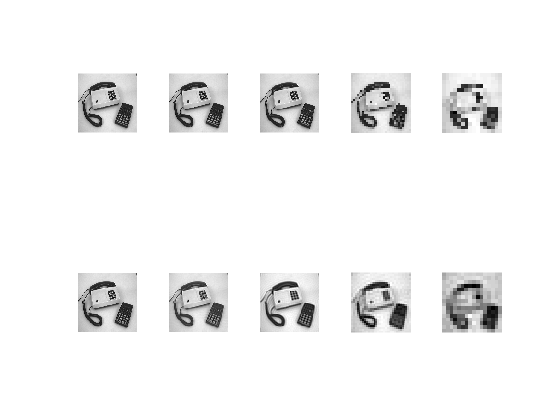

figure();
img = phonecalc256;
smoothimg = img;
N=5;
for i=1:N
        if i>1
            % generate subsampled versions
            img = rawsubsample(img);
            smoothimg = ideal(smoothimg, 0.25);
            smoothimg = rawsubsample(smoothimg);
        end
    subplot(2, N, i)
    showgrey(img)
    subplot(2, N, i+N)
    showgrey(smoothimg)
end

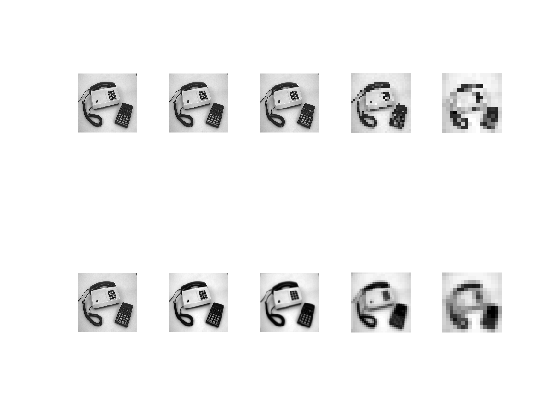


figure();
img = phonecalc256;
smoothimg = img;
N=5;
for i=1:N
        if i>1
            % generate subsampled versions
            img = rawsubsample(img);
            smoothimg = gaussfft(smoothimg, 0.4);
            smoothimg = rawsubsample(smoothimg);
        end
    subplot(2, N, i)
    showgrey(img)
    subplot(2, N, i+N)
    showgrey(smoothimg)
end